# Classify ECG Signals Using LSTMs

In this example, we will use LSTMs and time-frequency analysis to classify Electrocardiogram (ECG) data.

clear

## Introduction

ECGs records the electrical activity of a person's heart over time. Physicians use ECGs to visually detect whether a patient's heartbeat is normal or irregular.

We will be creating an LSTM Network to determine the presence of an irregular heartbeat called Atrial Fibrilation (AFib). This occurs when the heart's upper chambers beat out of coordination with the heart's lower chambers.

## Load and Visualize Data

The data for this example consists of a set of ECG signals sampled at 300 Hz and divided into 2 classes:

- N = Normal (738 signals)

- A = AFib (5050 signals)

The original ECG data comes from the PhysioNet 2017 Challenge, which is available at [https://physionet.org/challenge/2017/.](https://physionet.org/challenge/2017/.)

load PhysionetData.mat

ans = 5×1 cell array
    {1×9000  double}
    {1×9000  double}
    {1×18000 double}
    {1×9000  double}
    {1×18000 double}


This adds two variables to our workspace:

- `Signals` - cell array that holds ECG Signals

- `Labels` - categorical array that holds corresponding ground-truth labels

Signals(1:5)

ans = 5×1 categorical array
     N 
     N 
     N 
     A 
     A 


Labels(1:5)

     A       738 
     N      5050 


summary(Labels)

Most of the ECG signals are 9000 samples long, but there is some variability. Let's create a histogram that shows the length of the signals.

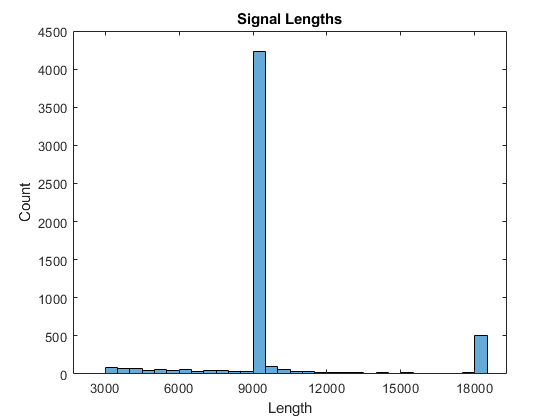

plotSignalLengths(Signals)

Visualize a segment of one signal from each class. Below are two common characteristics of AFib signals:

- Spaced out at irregular intervals.

- Lack a P wave, which pulses before the QRS complex in normal heartbeat.

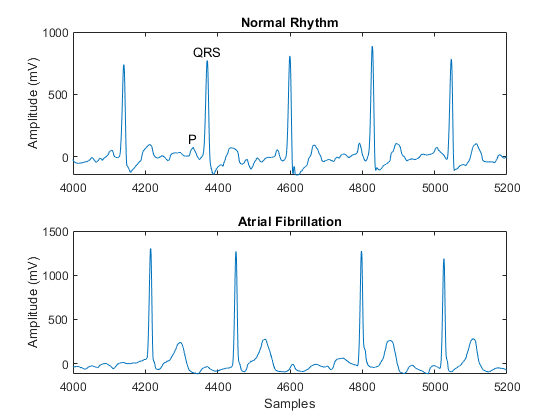

visualizeECGSignals(Signals)

## Prepare Data for Training

Since the ECG Signals are different lengths, we need to first pad and truncate them so they are all 9000 samples long. 

The function segmentSignals ignores signals with fewer than 9000 samples. If the signal over 9000 samples, segmentSignals breaks it into as many 9000-sample segments as possible and ignores the remaining samples.

For example, a signal with 18500 samples becomes two 9000-sample signals and the remaining 500 samples are ignored.

[Signals,Labels] = segmentSignals(Signals,Labels);

## Splitting Dataset into Training and Test Sets

Partition the dataset so that 90% of the signals are used for training our network and 10% are used to test our network.

Split the signals according to classes:

afibX = Signals(Labels=='A');
afibY = Labels(Labels=='A');

normalX = Signals(Labels=='N');
normalY = Labels(Labels=='N');

Use `dividerand` to divide targets from each class randomly into training and testing sets.

[trainIndA,~,testIndA] = dividerand(718,0.9,0.0,0.1);
[trainIndN,~,testIndN] = dividerand(4937,0.9,0.0,0.1);

XTrainA = afibX(trainIndA);
YTrainA = afibY(trainIndA);

XTrainN = normalX(trainIndN);
YTrainN = normalY(trainIndN);

XTestA = afibX(testIndA);
YTestA = afibY(testIndA);

XTestN = normalX(testIndN);
YTestN = normalY(testIndN);

## Handling Data Imbalance with Oversampling

Since over 80% of the signals are Normal, the classifier would learn that it can achieve a high accuracy by classifying all the signals as Normal. 

To avoid this bias, we duplicate the AFib signals until we have an equal number of Normal and AFib signals. This duplication is called oversampling, and it is one form of data augmentation used in deep learning.

- Training - Use first 4438 Normal signals and use `repmat` to repeat the first 634 AFib signals

- Test - Use first 490 Normal signals, and use `repmat` to repeat the first 70 AFib signals

XTrain = [repmat(XTrainA(1:634),7,1); XTrainN(1:4438)];
YTrain = [repmat(YTrainA(1:634),7,1); YTrainN(1:4438)];

XTest = [repmat(XTestA(1:70),7,1); XTestN(1:490)];
YTest = [repmat(YTestA(1:70),7,1); YTestN(1:490);];

The distribution between normal and AFib signals is now evenly balanced.

summary(YTrain)

     A      4438 
     N      4438 


summary(YTest)

     A      490 
     N      490 


## Define LSTM Architecture

LSTM networks can learn long-term dependencies between time steps of sequence data. This example uses the bidirectional LSTM layer `bilstmLayer`, as it looks at the sequence in both forward and backward directions.

Because the input signals have one dimension each, specify the input size to be sequences of size 1. Specify a bidirectional LSTM layer with an output size of 100 and output the last element of the sequence. This command instructs the bidirectional LSTM layer to map the input time series into 100 features and then prepares the output for the fully connected layer. Finally, specify two classes by including a fully connected layer of size 2, followed by a softmax layer and a classification layer. 

layers = [ ...
    sequenceInputLayer(1)
    bilstmLayer(100,'OutputMode','last')
    fullyConnectedLayer(2)
    softmaxLayer
    classificationLayer
    ];

## Set Training Options

Use the training options that are set for you.

options = trainingOptions('adam', ...
    'MaxEpochs',10, ...
    'MiniBatchSize', 150, ...
    'InitialLearnRate', 0.01, ...
    'SequenceLength', 1000, ...
    'GradientThreshold', 1, ...
    'ExecutionEnvironment',"auto",...
    'plots','training-progress', ...
    'Verbose',false);

## Train the Network

Train the network using the following command:

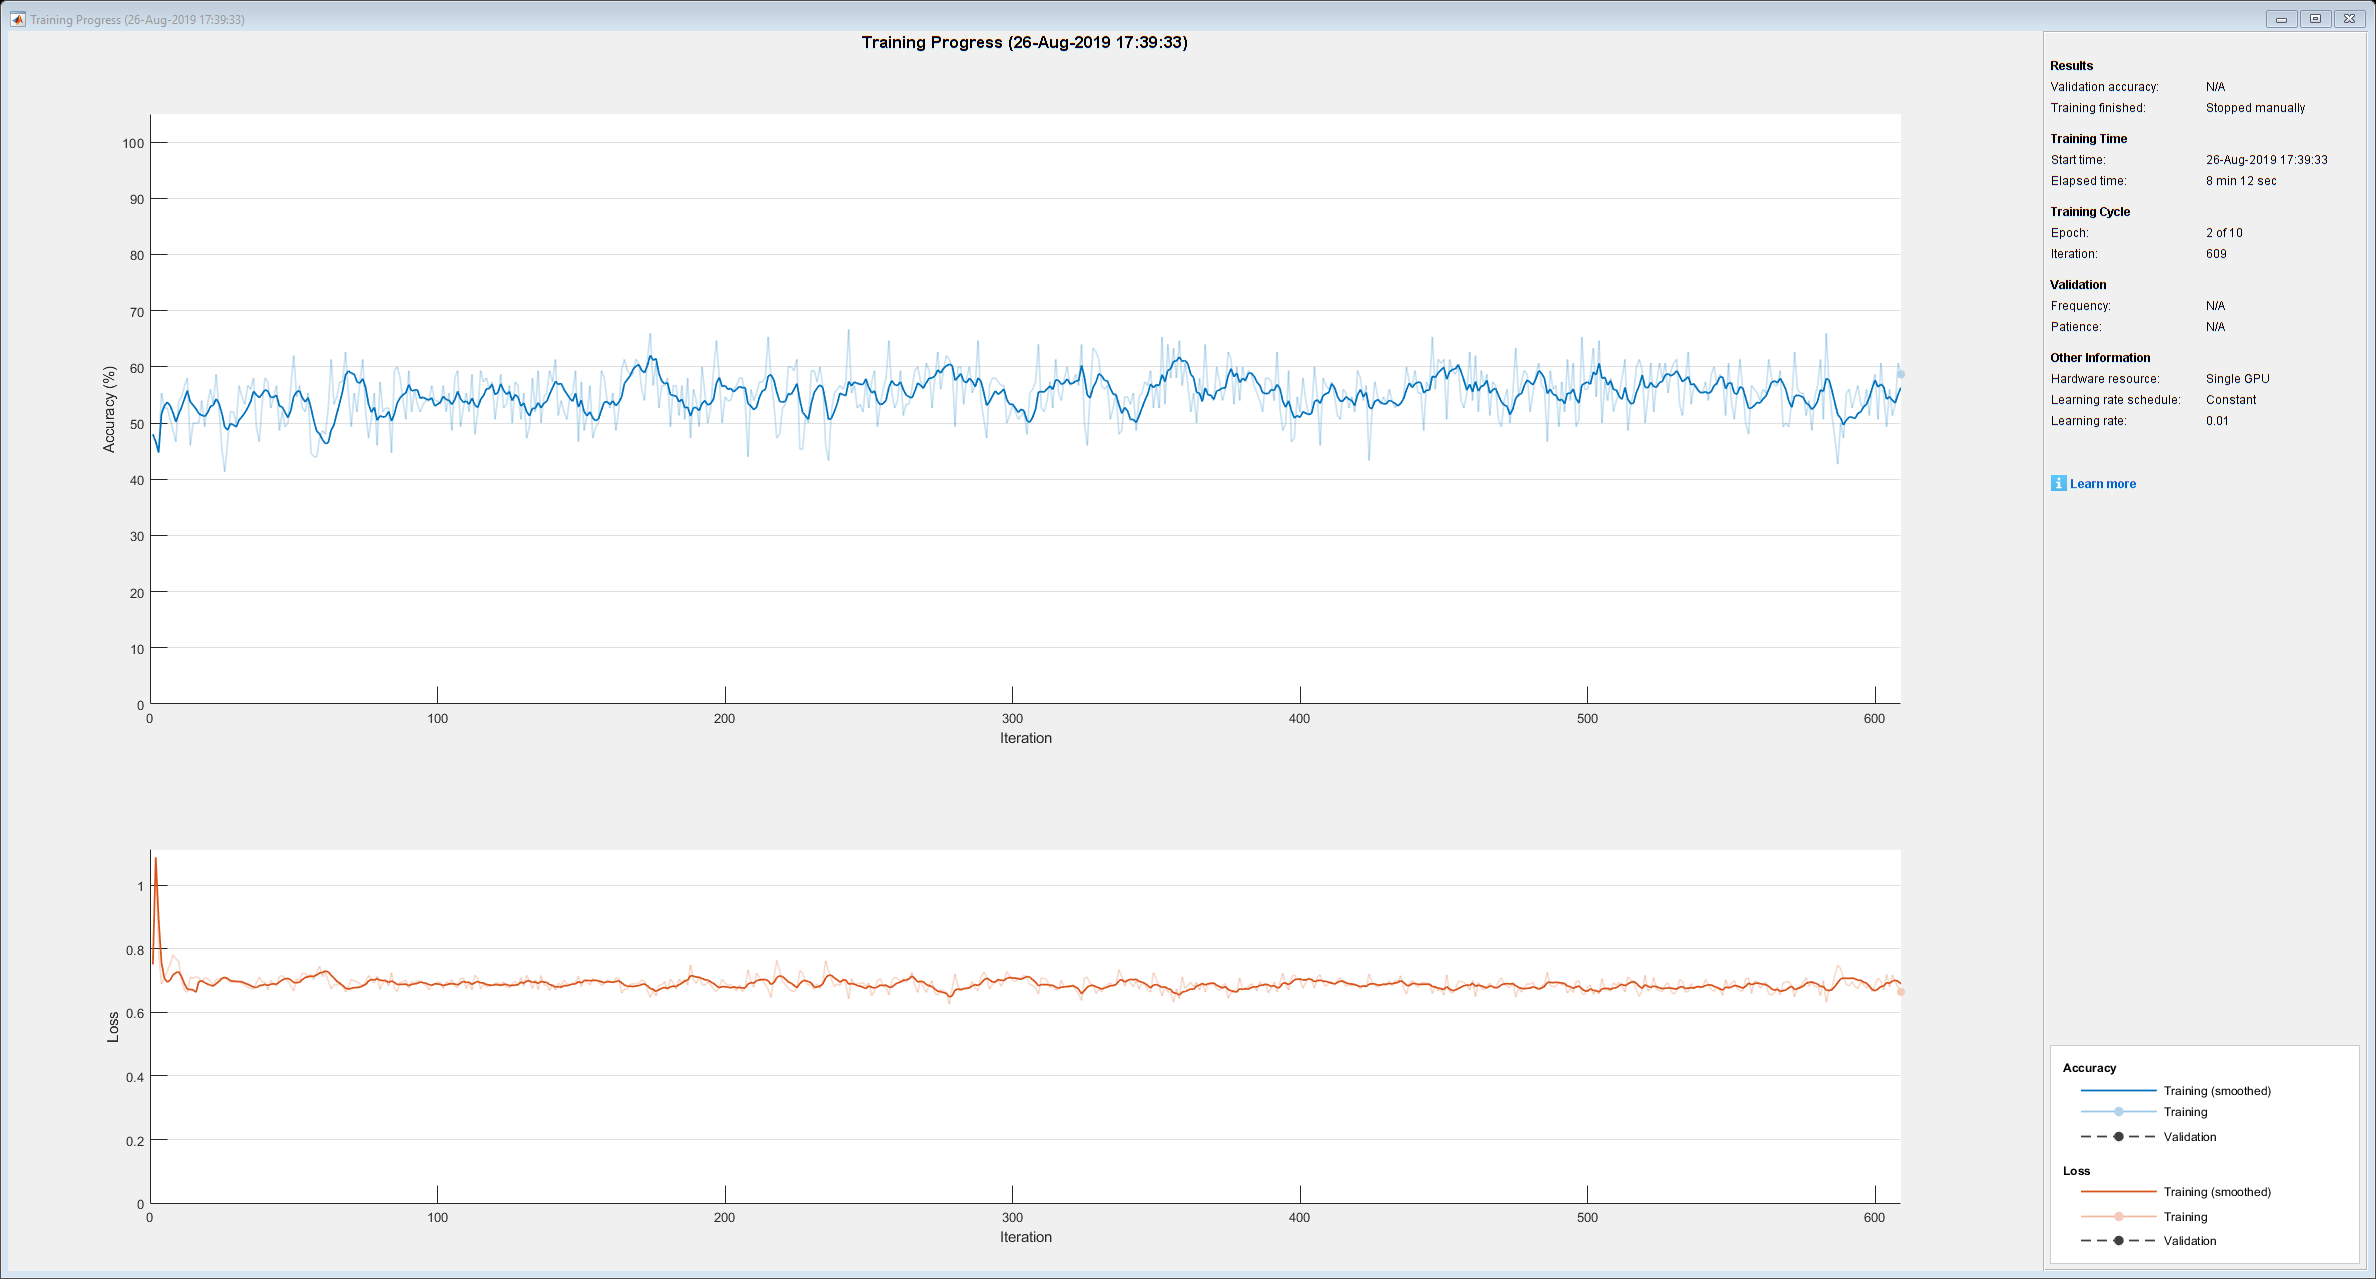

doTrain = false;


if doTrain
    net = trainNetwork(XTrain,YTrain,layers,options);
else
    load ECGNetwork.mat
end


The top subplot of the training-progress plot represents the training accuracy, which is the classification accuracy on each mini-batch. The bottom subplot displays the training loss, which is the cross-entropy loss on each mini-batch. When training progresses successfully, this value typically decreases towards zero.

## View the Results

Let's test our model on the test data. 

testPred = classify(net,XTest,'SequenceLength',1000);

LSTMAccuracy = 59.5918

Calculate the testing accuracy and visualize the classification performance as a confusion matrix.

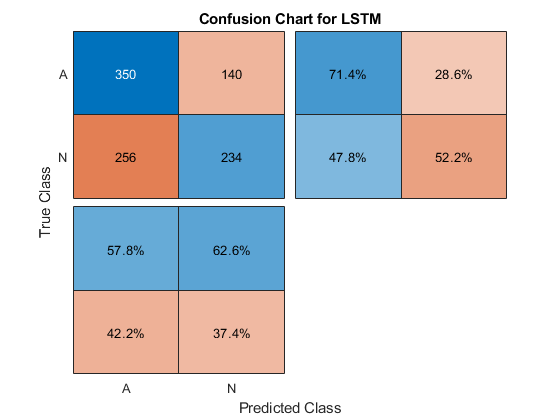

LSTMAccuracy = sum(testPred == YTest)/numel(YTest)*100
figure
ccLSTM = confusionchart(YTest,testPred);
ccLSTM.Title = 'Confusion Chart for LSTM';
ccLSTM.ColumnSummary = 'column-normalized';

ccLSTM.RowSummary = 'row-normalized';

This confusion matrix is similar to the training confusion matrix. The overall testing accuracy is around 55%.

## Improve Performance with Feature Extraction

Feature extraction from the data can help improve the training and testing accuracies of the classifier. To decide which features to extract, this example follows an approach that computes time-frequency (TF) moments. Each moment can be used as a one-dimensional feature to input to the LSTM. 

We will explore the following TF moments:

- Instantaneous frequency (`instfreq`)

- Spectral entropy (`pentropy`)

**Instantaneous Frequency**

The `instfreq` function estimates the time-dependent frequency of a signal as the first moment of the power spectrogram. The function computes a spectrogram using short-time Fourier transforms over time windows. In this example, `instfreq`, uses a buffer length, n, to compute the spectrogram, whcih results in 255 time windows for a signal of 9000 samples. The 255-long time outputs of the function correspond to the center of the time windows.

Visualize the instantaneous frequency for each type of signal.

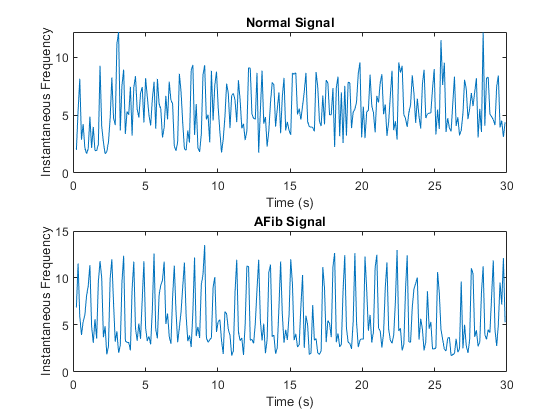

fs = 300;
normal = Signals{1};
aFib = Signals{4};

[instFreqN,tN] = instfreq(normal,fs);
[instFreqA,tA] = instfreq(aFib,fs);

plotInstFreq(tN,instFreqN,tA,instFreqA)

**Special Entropy**

The spectral entropy measures how spiky flat the spectrum of a signal is. A signal with a spiky spectrum, like a sum of sinusoids, has low spectral entropy. A signal with a flat spectrum, like white noise, has high spectral entropy. The `pentropy` function estimates the spectral entropy based on a power spectrogram. As with the instantaneous frequency estimation case, `pentropy` uses a buffer length, n, to compute the spectrogram which results in 255 time windows for a signal of 9000 samples. The 255-long time outputs of the function correspond to the center of the time windows.

Visualize the spectral entropy for each type of signal.

[pentropyA,tA2] = pentropy(aFib,fs);
[pentropyN,tN2] = pentropy(normal,fs);

plotPentropy(tN2,pentropyN,tA2,pentropyA);

Use `cellfun` to apply the `instfreq `and` pentropy` function to every cell in the training and testing sets. 

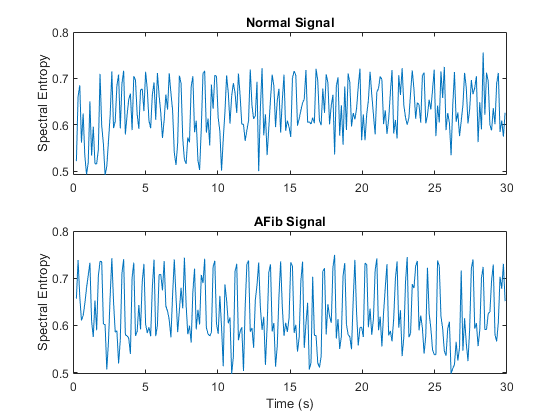

calculateFeatures = false;

if calculateFeatures 

    instfreqTrain = cellfun(@(x)instfreq(x,fs)',XTrain,'UniformOutput',false);
    instfreqTest = cellfun(@(x)instfreq(x,fs)',XTest,'UniformOutput',false);
    pentropyTrain = cellfun(@(x)pentropy(x,fs)',XTrain,'UniformOutput',false);
    pentropyTest = cellfun(@(x)pentropy(x,fs)',XTest,'UniformOutput',false);
else
    load ExtractedFeatures.mat
end

Concatenate the features such that each cell in the new training and testing sets has two dimensions, or two features. 

XTrain2 = cellfun(@(x,y)[x;y],instfreqTrain,pentropyTrain,'UniformOutput',false);
XTest2 = cellfun(@(x,y)[x;y],instfreqTest,pentropyTest,'UniformOutput',false);

Visualize the format of the new inputs. Each cell no longer contains one 9000-sample-long signal; now it contains two 255-sample-long features.

XTrain2(1:5)

ans = 5×1 cell array
    {2×255 double}
    {2×255 double}
    {2×255 double}
    {2×255 double}
    {2×255 double}


## Standardize the Data

The instantaneous frequency and the spectral entropy have very different means, which could impact training time and accuracy. 

One common practice is standardizing our dataset using the mean and standard deviation from the training and test sets (z-scoring). 

[XTrainSD,XTestSD] = standardizeData(XTrain2,XTest2);

## Modify LSTM Architecture

Since we extracted two features, our signal has two dimensions. We need to modify the sequence input layer to have an input sequence of 2 instead of 1. Modify the network in the deep network designer, and export it to the workspace.

layers = [ ...
    sequenceInputLayer(2)
    bilstmLayer(100,'OutputMode','last')
    fullyConnectedLayer(2)
    softmaxLayer
    classificationLayer
    ];

Specify the training options. Set the maximum number of epochs to 30 to allow the network to make 30 passes through the training data.

options = trainingOptions('adam', ...
    'MaxEpochs',30, ...
    'MiniBatchSize', 150, ...
    'InitialLearnRate', 0.01, ...
    'GradientThreshold', 1, ...
    'ExecutionEnvironment',"auto",...
    'plots','training-progress', ...
    'Verbose',false);

## Train Network with Features

Train the LSTM network with the specified training options and layer architecture by using `trainNetwork`.

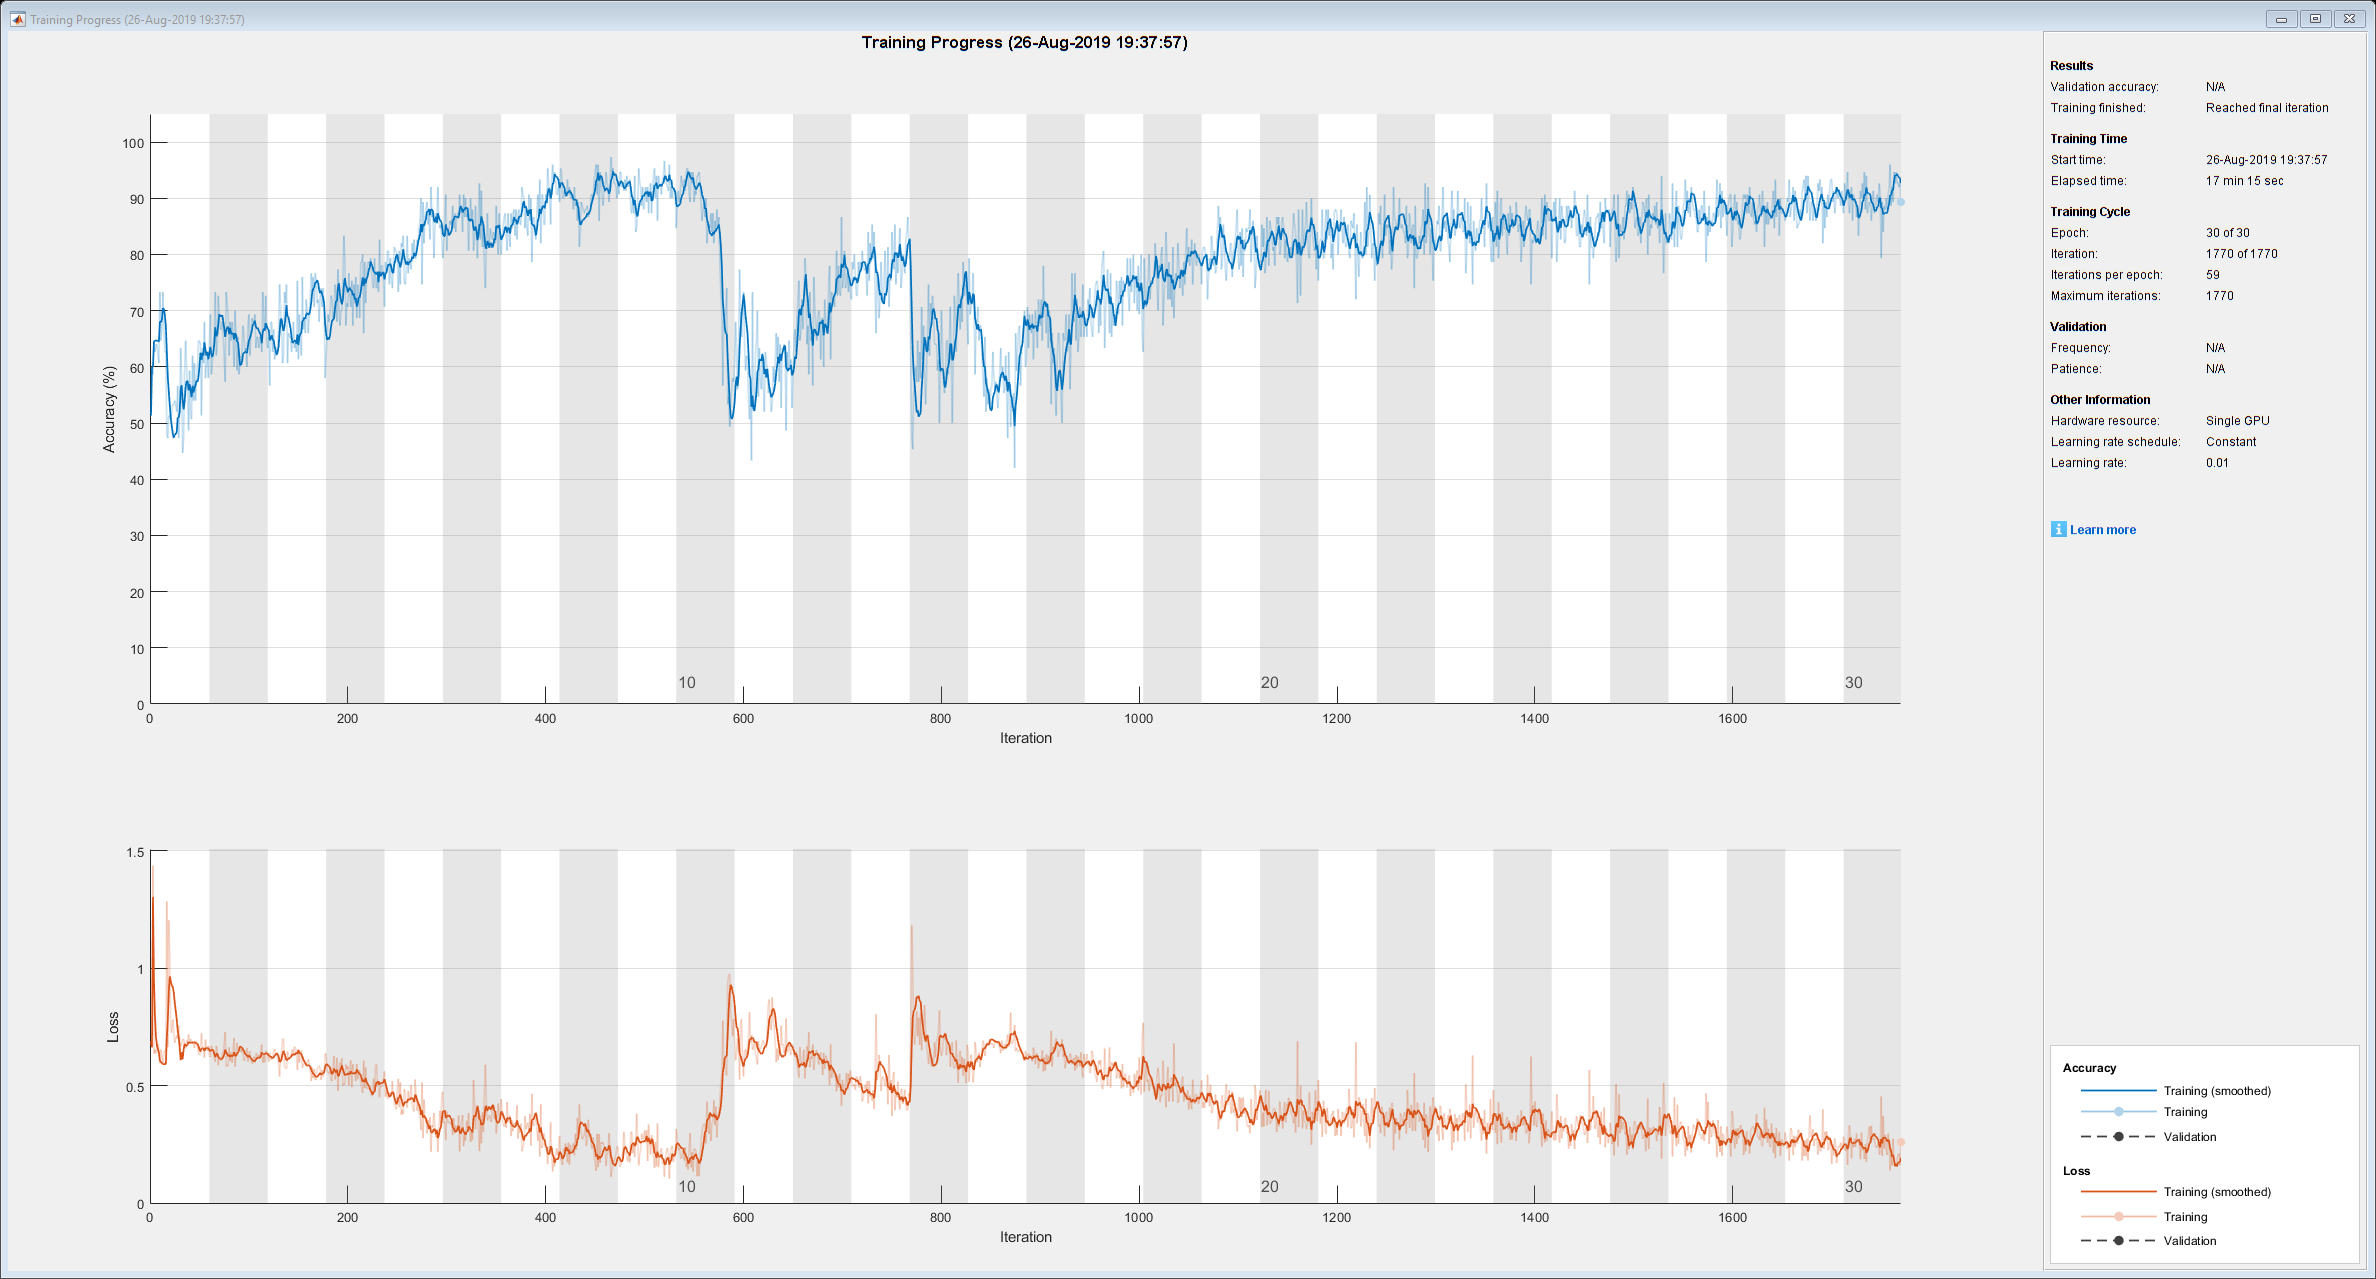

doTrain = false;


if doTrain
    net2 = trainNetwork(XTrainSD,YTrain,layers,options);
else
    load ECGFeatureExtractionNetwork.mat
end


LSTMAccuracy = 89.4898

There is a great improvement in the training accuracy, which is now greater than 90%. The cross-entropy loss trends towards 0. Furthermore, the time required for training decreases because the TF moments are shorter than the raw sequences.

## Visualize Test Accuracy

Classify the testing data with the updated network. Plot the confusion matrix to examine the testing accuracy. 

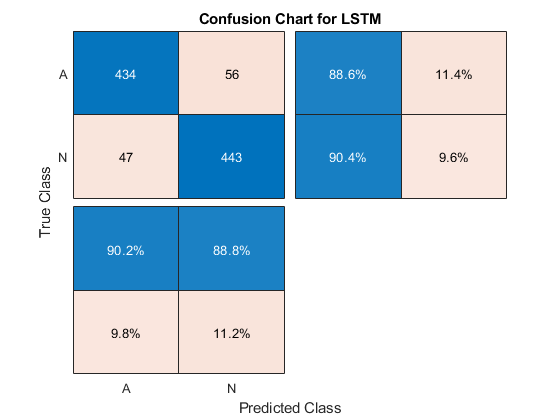

testPred2 = classify(net2,XTestSD);

LSTMAccuracy = sum(testPred2 == YTest)/numel(YTest)*100
figure
ccLSTM = confusionchart(YTest,testPred2);

ccLSTM.Title = 'Confusion Chart for LSTM';
ccLSTM.ColumnSummary = 'column-normalized';
ccLSTM.RowSummary = 'row-normalized';

## Key Takeaways

- LSTM networks are one approach for signal classification

- Oversampling used to avoid classification bias with imbalanced datasets

- LSTMs may not perform well on raw signal.

- Feature extraction prior to training can improve accuracy of LSTM